##  Decision Tree (DT) Model Selection

Sin Sze Li 210035720

### 1) Data preparation

close all; clc; clear all

% Load the training data
tblTrain = readtable('training_set.csv');

% Select related rows and columns
tblTrain = tblTrain(:, 2:end);
head(tblTrain)

ans = 8×11 table
    baseline_value    accelerations    fetal_movement    uterine_contractions    light_decelerations    severe_decelerations    prolongued_decelerations    abnormal_short_term_var    abnormal_short_term_var_mean    abnormal_long_term_var    fetal_health
    ______________    _____________    ______________    ____________________    ___________________    ____________________    ________________________    _______________________    ____________________________    ______________________    ____________

         147                  0                0                0.002                   0.002       


% Split the data to features and classes
Train_X = tblTrain(: ,1:end-1);             %Training Features
Train_y = tblTrain(: ,end);                 %Training Classes

### 2) Bayesian optimization 

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.13729 |      1.1731 |     0.13729 |     0.13729 |           56 |          100 |
|    2 | Best   |     0.11515 |     0.22804 |     0.11515 |     0.11688 |           34 |           67 |
|    3 | Best   |    0.086087 |     0.15983 |    0.086087 |     0.08609 |           31 |           22 |
|    4 | Accept |    0.099099 |     0.12899 |    0.086087 |    0.086097 |           85 |           36 |
|    5 | Accept |     0.10826 |     0.25344 |    0.086087 |      0.1005 |           10 |           20 |
|    6 | Accept |    0.088783 |     0.10023 |    0.086087 |    0

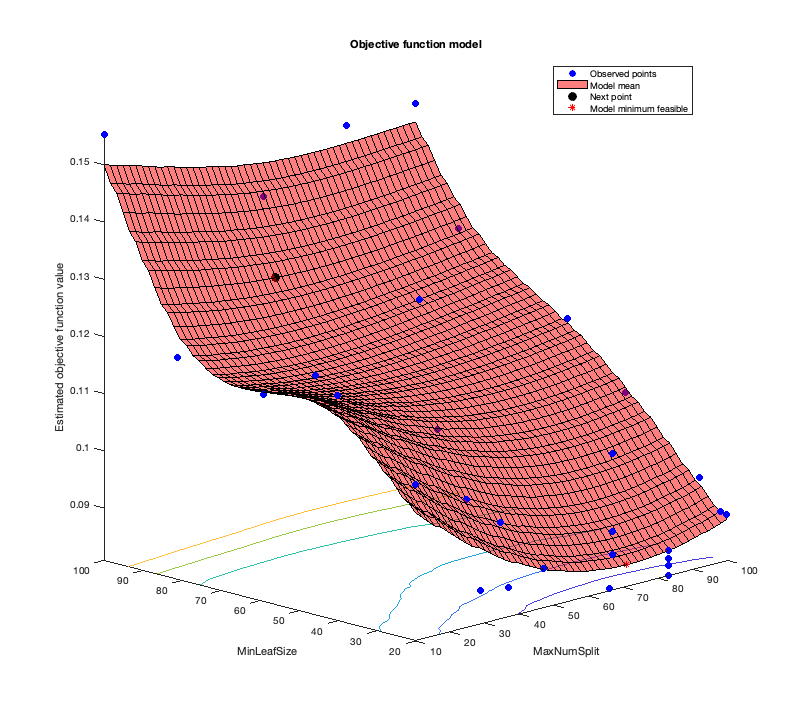

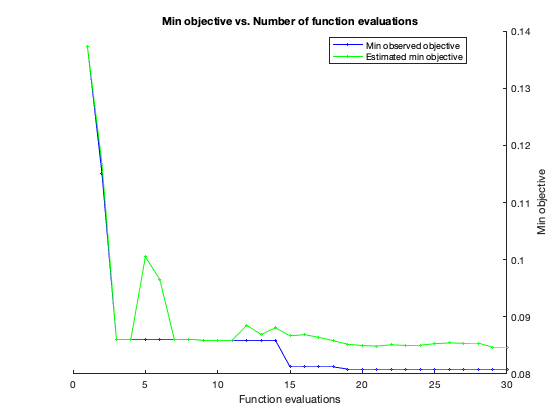


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 22.1627 seconds
Total objective function evaluation time: 4.3558

Best observed feasible point:
    MaxNumSplit    MinLeafSize
    ___________    ___________

        83             20     

Observed objective function value = 0.080847
Estimated objective function value = 0.085217
Function evaluation time = 0.094835

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeafSize
    ___________    ___________

        67             20     

Estimated objective function value = 0.08472
Estimated function evaluation time = 0.10431



rng('default') % for reproducibility

% Hyperparameters for optimization and their ranges
MaxNumSplit = optimizableVariable('MaxNumSplit',[10,100],'Type','integer');
MinLeafSize = optimizableVariable('MinLeafSize',[20, 100],'Type','integer');
hyperparamtersRF = [MaxNumSplit;MinLeafSize];

% Optimize the hyperparameters by bayesian optimizer
% f1_objective can be found at the end of the script
results = bayesopt(@(params)f1_objective(params,Train_X,Train_y),hyperparamtersRF,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

Therefore, the best combination of hyperparameters is MaxNumSplit = 67 and MinLeaf = 20. These hyperparameters are passed to the final model.

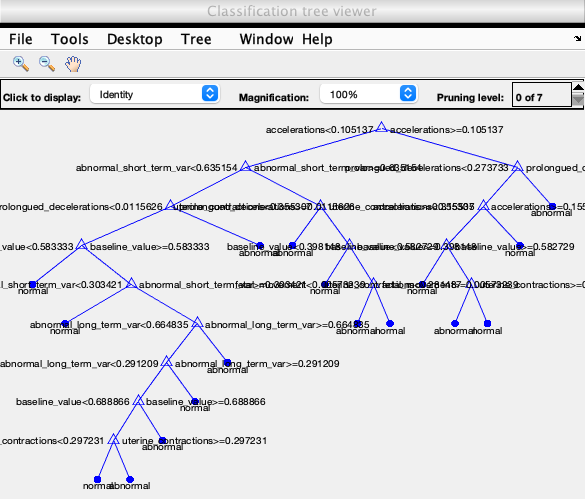

% Train the best combination model according to bayesian optimizer
Model_DT = fitctree(Train_X,Train_y,'MaxNumSplits',67,'MinLeafSize',20); 

% Predict the labels and posterior probabilities of each class
[label_DT, score_DT] = predict(Model_DT, Train_X);

% View decision tree
view(Model_DT,'mode','graph') 


% Confusion matrix
cm = confusionchart(table2cell(Train_y),label_DT)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: {2×1 cell}

  Show all properties


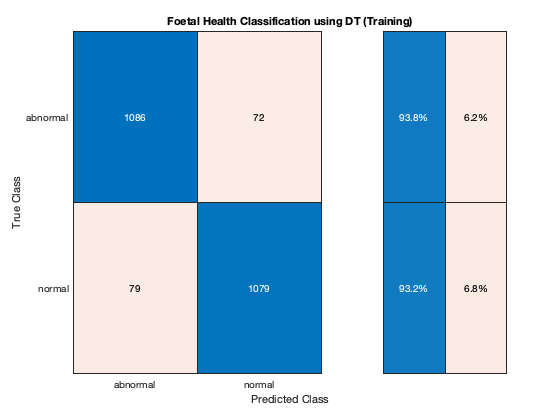

cm.RowSummary = 'row-normalized';
cm.Title = 'Foetal Health Classification using DT (Training)';


% Define the TP, TN, FP and FN
[confMat,order] = confusionmat(table2cell(Train_y),label_DT);
TP = confMat(1, 1); 
TN = confMat(2, 2);
FP = confMat(2, 1);
FN = confMat(1, 2);

% Calculate the accuracy, recall, precision and F1 score
acc = (TP+TN)/(TP+TN+FP+FN)

acc = 0.9348

recall = TP/(TP+FN)

recall = 0.9378

precision = TP/(TP+FP)

precision = 0.9322

F1 = 2*recall*precision/(recall+precision)

F1 = 0.9350


table_result = table(acc',recall',precision',F1', 'VariableNames', {'Accuracy','Recall','Precision','F_1'});
display(table_result)

table_result = 1×4 table
    Accuracy    Recall     Precision     F_1 
    ________    _______    _________    _____

     0.9348     0.93782     0.93219     0.935


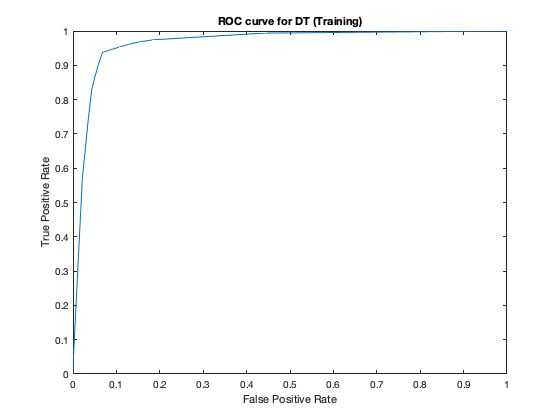


% ROC curve
true_class_DT = table2array(Train_y) =="abnormal";
true_class_DT = double(true_class_DT);
[X Y T AUC] = perfcurve(true_class_DT, score_DT(:, 1), 1);

figure;
plot(X, Y);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC curve for DT (Training)');

### 3) Save the trained model to .mat file (commented out to avoid saving file repeatedly)

% % Load the testing set
% tblTest = readtable('testing_set.csv');
% 
% % Select related rows and columns
% tblTest = tblTest(:, 2:end);
% 
% % Split the data to features and classes
% Test_X = tblTest(: ,1:end-1);             %Training Features
% Test_y = tblTest(: ,end);                 %Training Classes
% 
% save('DT_Final_Model.mat', 'Model_DT', 'Test_y', 'Test_X')

### 4) Function

function f1 = f1_objective(params,X,Y)
        Model=fitctree(X,Y,'CrossVal', 'on', 'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeafSize);
        %Calculate F1 of each combination
        Predicted=kfoldPredict(Model);
        confMat=confusionmat(table2cell(Y),Predicted);   
        recall=confMat(1,1)/sum(confMat(1,:));
        precision=confMat(1,1)/sum(confMat(:,1));
        f1 = 2*recall*precision/(recall+precision);
        f1=1-f1;
end